CDo = 0.0253;

CLCDMax = 0;

for i = 1:211    %353 %For Flaps
    
    %AoA(i) = -21.1+i*0.1; %For Flaps
    
    AoA(i) = -10.1+i*0.1;
    
    [CL(i),CD(i)] = Vanguard_VLM(AoA(i));
    
    if CL(i)/(CD(i)+CDo) > CLCDMax
        
        CLCDMax = CL(i)/(CD(i)+CDo);
        
    end
    
end
CLCDMax

CLCDMax = 16.4260


CL1 = CL1/sqrt(1-0.6233^2)

CL1 =    -0.7912   -0.2272    0.2187    0.5423    0.9215    1.0112    1.1052    1.1956    1.2663    1.3176    1.3928    1.4521    1.5011    1.5294    1.5342


CL2 = CL2/sqrt(1-0.6233^2)

CL2 =    -0.9937   -0.5079    0.0529    0.2742    0.5793    0.8841    0.9927    1.0414    1.0583    1.0634    1.0976    1.1185    1.1124    1.1191    1.1378


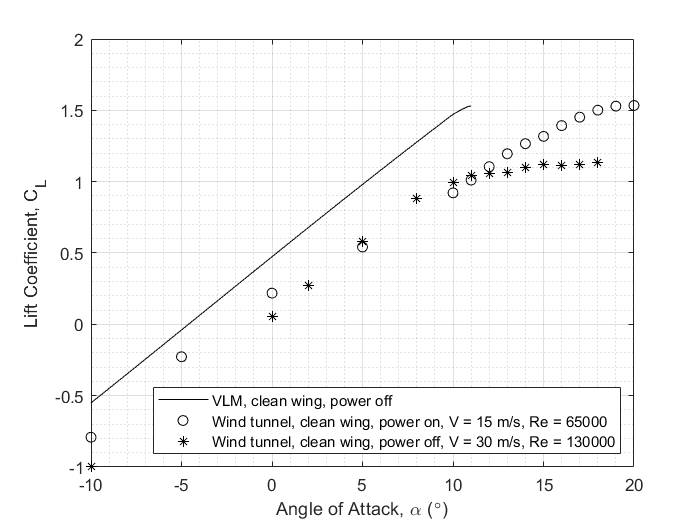



figure
plot(AoA,CL,'black')
hold on
scatter(AoA1,CL1,'black','Marker','o')
scatter(AoA2,CL2,'black','Marker','*')
hold off
grid on
grid minor
xlabel('Angle of Attack, \alpha ({\circ})')
ylabel('Lift Coefficient, C_L')
legend('VLM, clean wing, power off','Wind tunnel, clean wing, power on, V = 15 m/s, Re = 65000','Wind tunnel, clean wing, power off, V = 30 m/s, Re = 130000', 'Location','southeast')

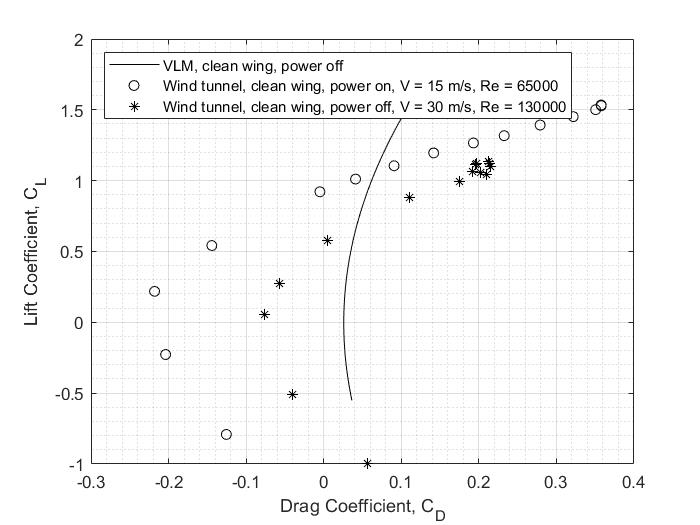


figure
plot(CD+CDo,CL, 'black')
hold on
scatter(CD1,CL1,'black','Marker','o')
scatter(CD2,CL2,'black','Marker','*')
hold off
grid on
grid minor
xlabel('Drag Coefficient, C_D')
ylabel('Lift Coefficient, C_L')
legend('VLM, clean wing, power off','Wind tunnel, clean wing, power on, V = 15 m/s, Re = 65000','Wind tunnel, clean wing, power off, V = 30 m/s, Re = 130000', 'Location','northwest')